# Quadcopter Basics - Movement

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

A quadcopter that hovers at a fixed position in the air might be useful, but we still need to fly the quadcopter into position, which will require some non-hovering flight. This script investigates the different aspects of quadcopter motion that can be combined into any possible path. Elevation measures vertical position, while pitch, roll, and yaw are each forms of rotation around the primary $x$, $y$, and $z$-axes. Using the parameters we calculated in [Quadcopter Basics](matlab:open('.\QuadcopterBasicsSoln.mlx')), we'll be able to induce each type of motion by adjusting the rotational speeds of the propellers.

## Quadcopter Simulation

Load the quadcopter parameters and open the model. Choose whichever configuration you want to work with, but recognize that the animation will always draw a +-configuration quadcopter even when the dynamics are from an x-configuration.

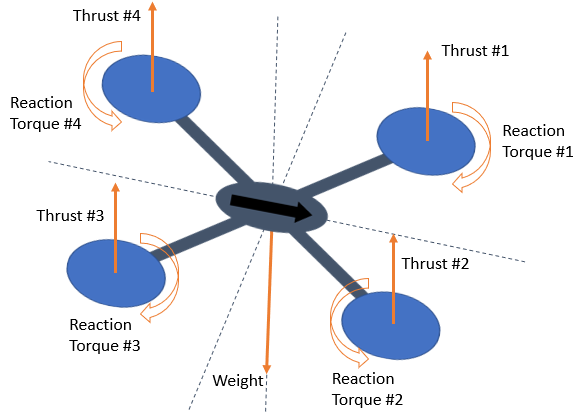

clear quad_m W w
load plus_quad_params.mat quad_m W w
open_system("UAV_Sim.slx")

To model the movement of the quadcopter, we have to solve at least two sets of equations at each timestep in a simulation. An easier way is to do all this in Simulink, where we only need to generate the propeller speeds and, later, the control signals. First, we compute the total forces and moments due to the propeller speeds, as described in the previous script ([Quadcopter Basics](matlab:open('.\QuadcopterBasicsSoln.mlx'))). 

$\left[\matrix{T \cr \mathbf{Q}}\right] = A\mathbf{\omega}^2$   $\Leftrightarrow$    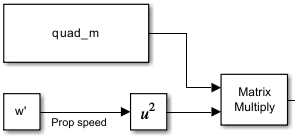

Secondly, we need to apply both the thrust forces and the moments in the directions defined by the current orientation of the quadcopter. Our computations have all been in the body frame, where the origin is at the center of the quadcopter, $+x$ is forward, $+y$ is to the right, and $+z$ is downwards. To transform these values into the apparent motion of an outside observer in a different reference frame, we use rotation matrices, as described in [Rigid Transformations](matlab:open('.\RigidTransformsSoln.mlx')). 

$R \left[\matrix{0 \cr 0 \cr W}\right] = \text{Gravitational force in body frame}$   $\Leftrightarrow$  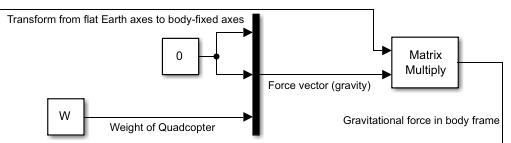

The complicated rotational calculations can be handled by the [6DOF](https://www.mathworks.com/help/aeroblks/6dofquaternion.html) block. The [UAV Animation block](https://www.mathworks.com/help/uav/ref/uavanimation.html) is also a standard block.

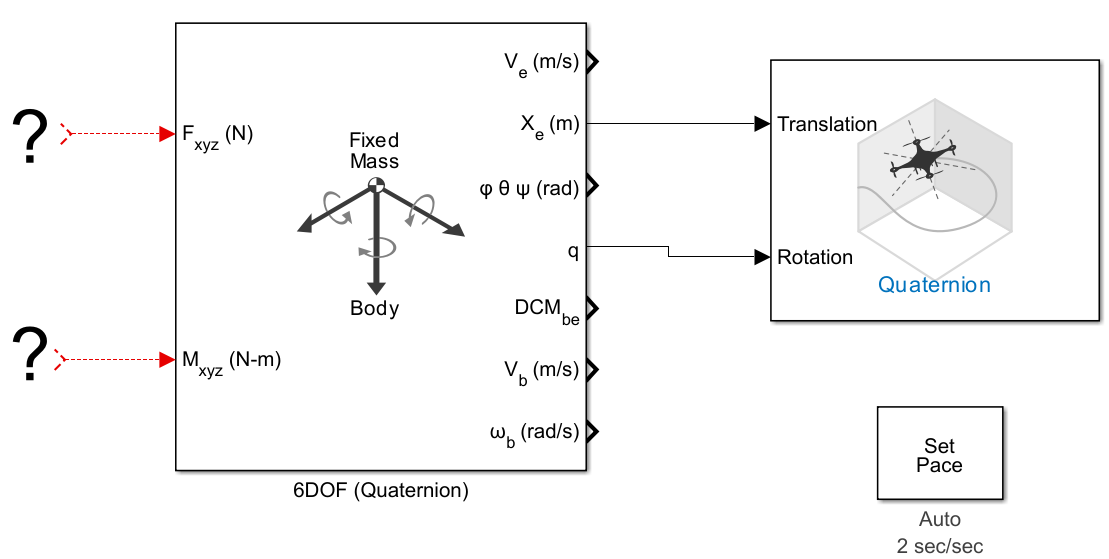

  **Try**. Let's try hovering first. You already checked that this should result in a hover in [Quadcopter Basics](matlab:open('./QuadcopterBasicsSoln.mlx')), so it is a good initial sanity check of the `UAV_Sim` model. 

w = [4000 4000 4000 4000];

sim("UAV_Sim_Soln.slx")

If all the forces are balanced, the quadcopter shouldn't move. Since we chose the model parameters to ensure that the thrust exactly counteracts the quadcopter's weight at 4000 rpm, this should not be a surprise.

## Quadcopter Movement - Elevation

Adjusting the elevation of a quadcopter is relatively simple. By increasing (green color, longer arrows) or decreasing (orange color, shorter arrows) the thrust of all four propellers (relative to the hover point), an upward or downward acceleration can be induced. This acceleration results in a change in elevation. 

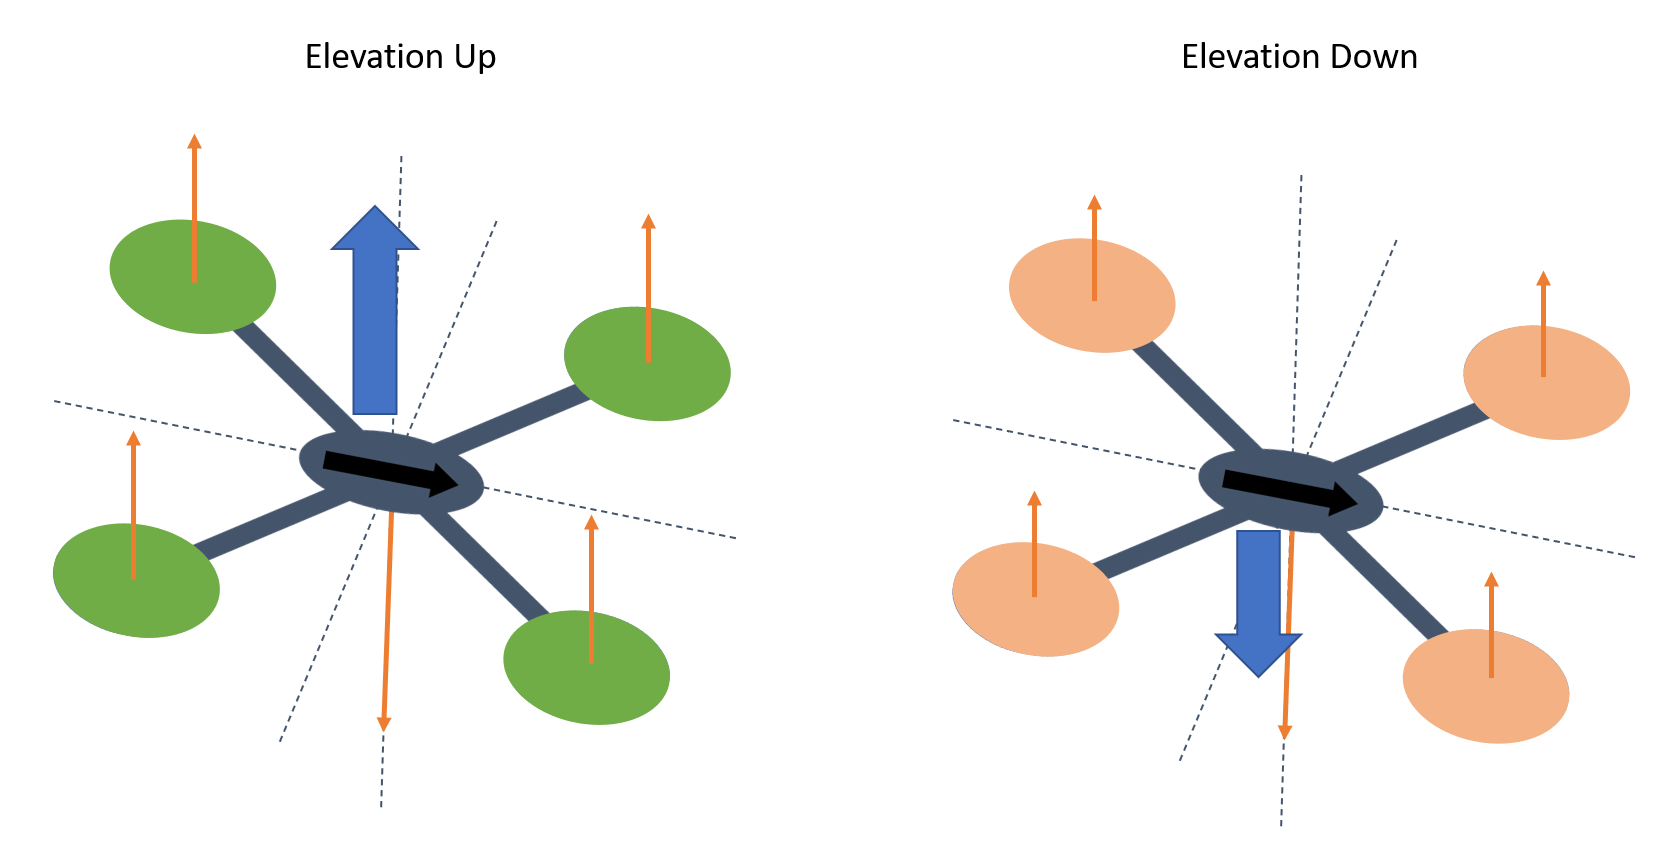

Next, let's try changing the elevation by moving all the propellers faster or slower. We can see the UAV drop down or rise up vertically, as all the propellers are balanced.

  **Try**. Set the rotational speed to be faster and slower than the hover speed of 4000 rpm. What happens?

speed = 4250;
w = [speed speed speed speed];
sim("UAV_Sim_Soln.slx")

## Pitch, Roll, and Yaw

Up to this point, the configuration was symmetric, but once we consider pitch, roll, and yaw, the configuration will matter significantly. Pitch is rotation around the $y$-axis, which sends the 'nose' of the quadcopter up or down relative to the $x$-$y$ plane. Roll is rotation around the $x$-axis, which tilts the quadcopter to the left or to the right. Yaw is rotation around the $z$-axis, changing direction without tipping the quadcopter. 

### Quadcopter Movement - Pitch

To move forward, the quadcopter must pitch forward. In the x-configuration, this can be caused by reducing the speed of the front two propellers relative to the speed of the two rear propellers. In the +-configuration, this requires reducing the speed of the first (front) propeller and increasing the speed of the third (rear) propeller. Once the angle has changed, level flight can be achieved by spinning the propellers such that the vertical component of the thrust exactly counteracts gravity, and the remaining thrust due to the angle will move the quadcopter in the xy-plane. 

**X-Configuration**

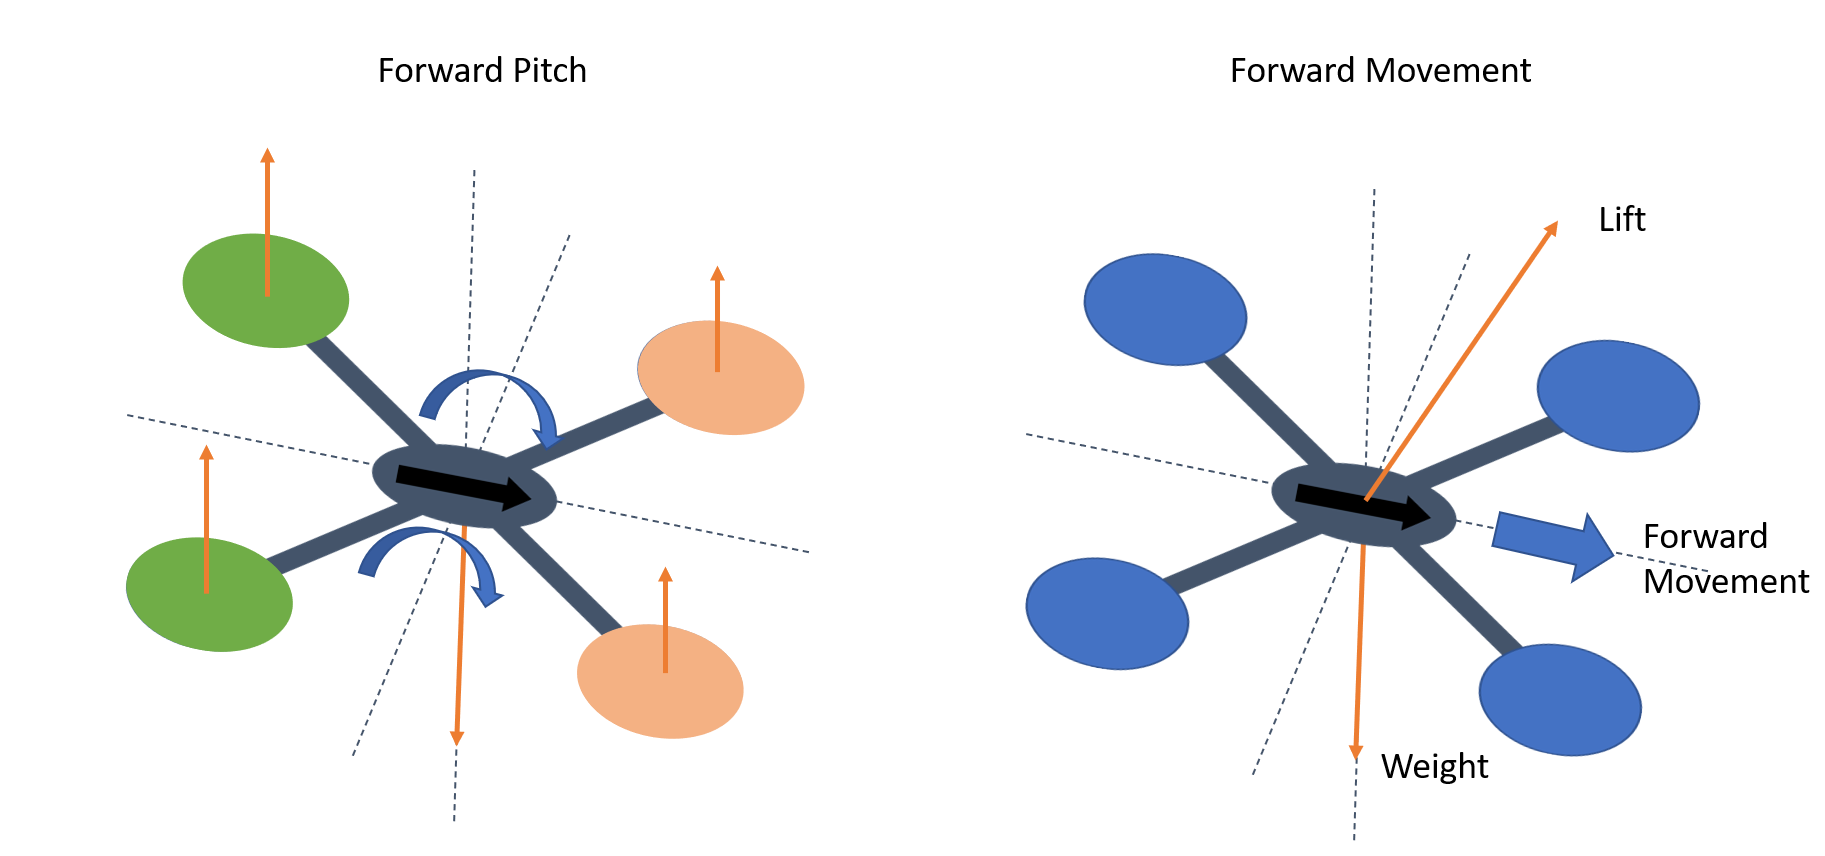

The total lift component of the thrust now points slightly forward of the vertical axis, inducing forward movement. Reverse movement can similarly be achieved by pitching backward. The mathematics and controls are exactly the same, just with a negative sign.

 **Pro-tip. **The UAV Animation block draws a +-configuration quadcopter where the #1 propeller arm faces north, and the inertial frame has $+z$ in the "down" direction. 

 **Exercise**. Considering the orientation of the quadcopter you have chosen, set values that make the quadcopter move forward. 

w = [4000 4000 4100 4100];  % for x-config
% w = [3900 4000 4100 4000] % for +-config
sim("UAV_Sim_Soln.slx");

 We can see that at larger values or longer runtimes, the drone tips over and goes unstable. You may be able to see the initial behavior more clearly if you change rotational speeds by less than 5% and shorten the simulation stop time to 3 or 4. This is because the model currently has no means to stop the asymmetric rotation, so we need to implement closed-loop feedback controllers to maintain the orientation. We will see this in future lectures.

### Quadcopter Movement - Roll

Similar to the forward/backward movement, for an x-configuration quadcopter, the speed of two propellers on the same side can be reduced, causing the quadcopter to roll left or right. Once the angle has changed, all the propellers are turned at the same speed, which should be sufficient to counteract the weight force. The total lift component of the thrust now points slightly left or right of the vertical axis, inducing lateral movement.

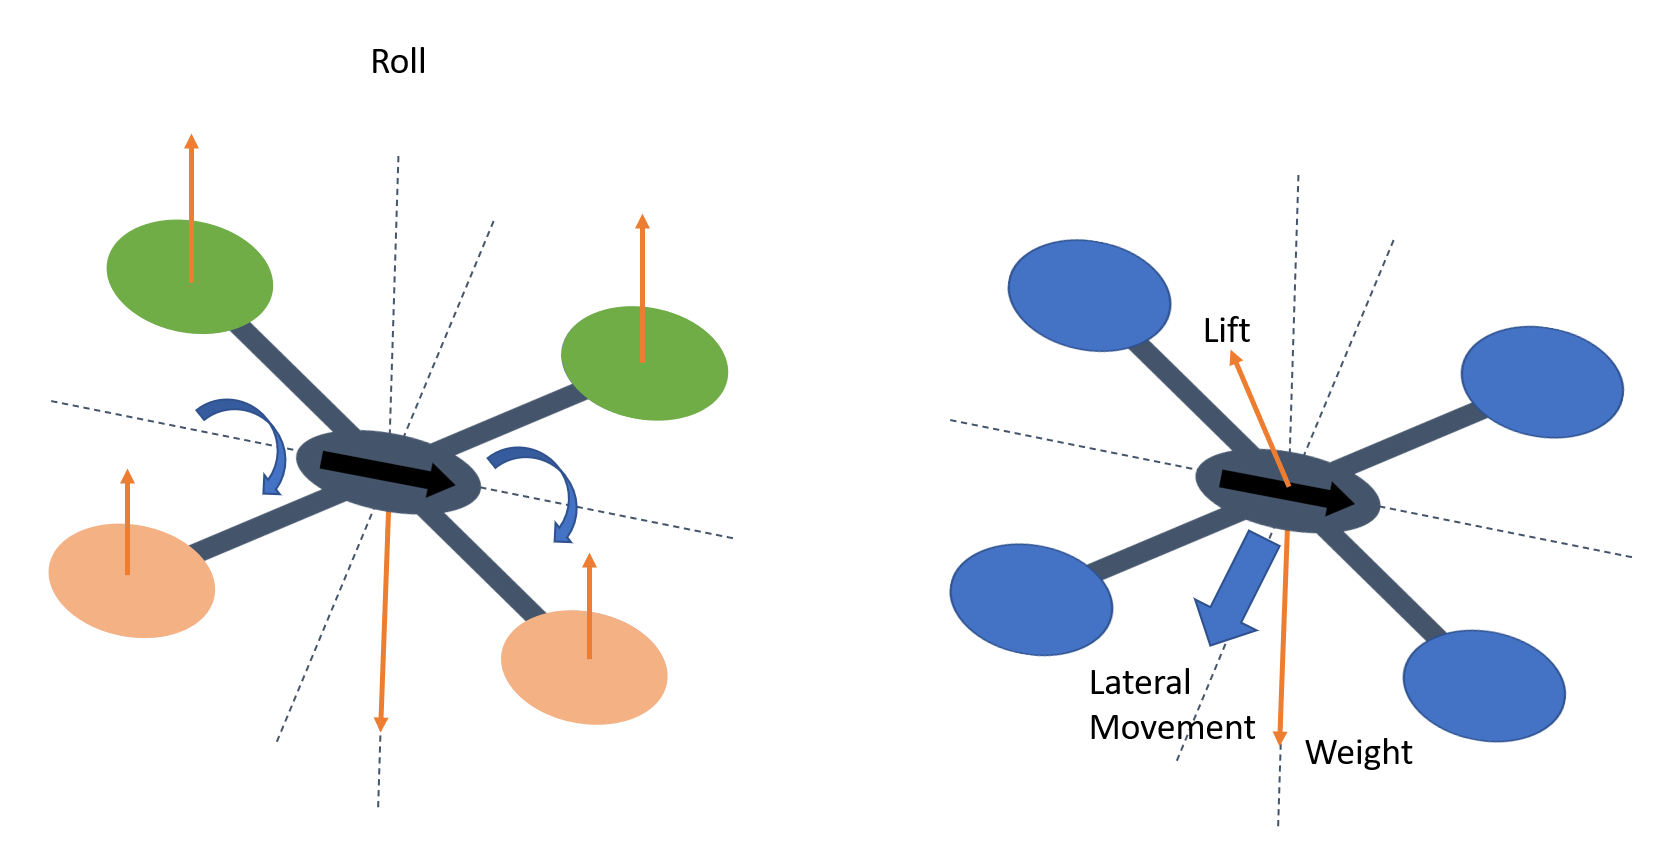

To induce a roll around the forward/backward axis in a +-configuration quadcopter, you need to change the relative rotational speeds of the #2 and #4 propellers.

 **Exercise**. Considering the orientation of the quadcopter you have chosen, set values that make the quadcopter roll to the right. What about rolling to the left? 

w = [4100 3900 3900 4100]  % For x-config
% w = [4000 3900 4000 4100] % for +-config
sim('UAV_Sim_Soln.slx')

Here we can see the drone moving laterally.

 **Reflect**. Comparing a +-configuration and an x-configuration, what changes about the sign patterns for roll/pitch torques when you increase a particular propeller thrust?

### Quadcopter Movement - Yaw 

The quadcopter can be rotated to the left or to the right around the vertical axis by adjusting the speeds of the opposing diagonal pairs of propellers. This action is independent of configuration. If one set is sped up, while the other slows down, it creates an imbalance in the reaction moments while still preserving the total thrust force. This can induce a rotation, which can be used to steer the quadcopter.

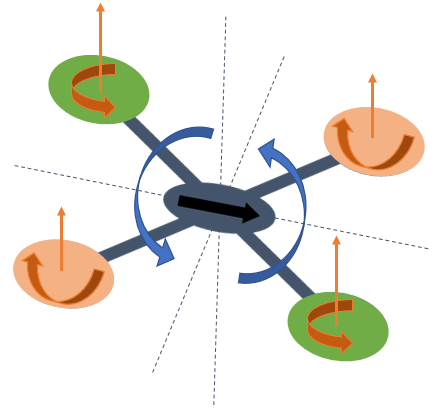

 **Exercise. **Choose angular velocities for each propeller that will result in a counterclockwise rotation of the quadcopter.

w = [3900 4100 3900 4100];
sim("UAV_Sim_Soln.slx");

 **Reflect**. What do you need to change to cause a clockwise rotation of the quadcopter?

## Next Steps

As shown in the simulations, while obtaining an open-loop response is possible, we need to develop more robust feedback controllers to ensure system stability and reliably follow a desired trajectory. Continue this in [QuadcopterControl](matlab:open('.\QuadcopterControlSoln.mlx')).

[⇦ Main Menu](matlab:open('MainMenu.mlx'))